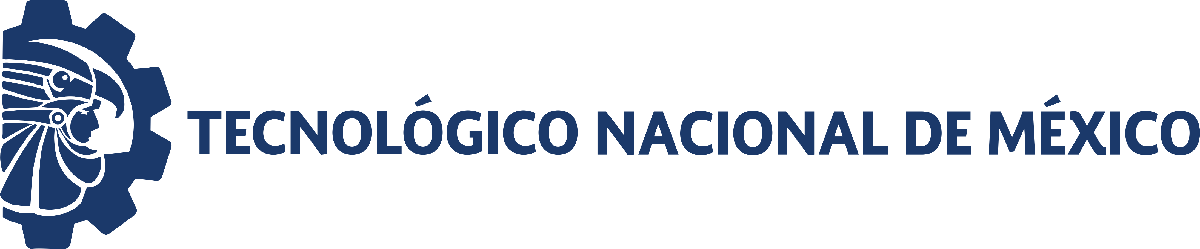                                 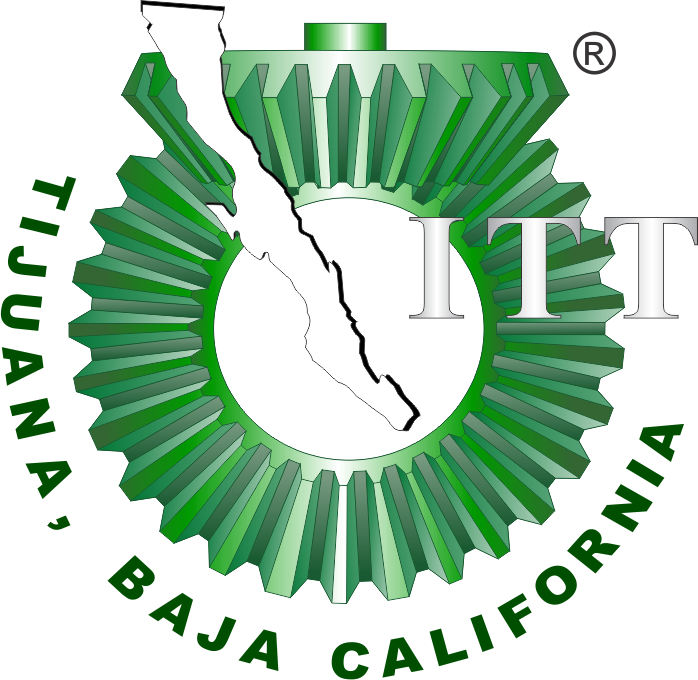

# Proyecto: Sistema Urinario Masculino (Hiperplasia Prostática Benigna)

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

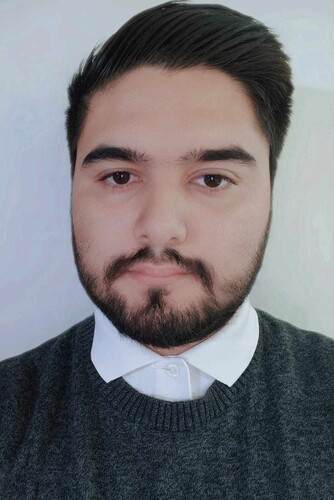 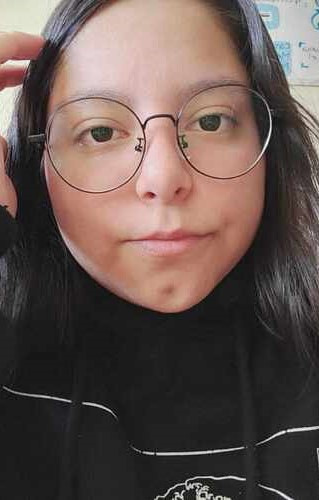 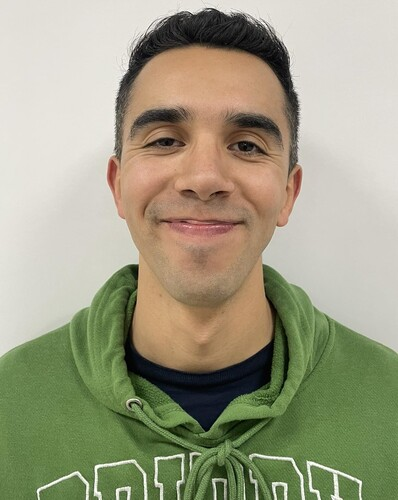

Nombre del alumno**: Delgado Soto José Sebastian, Escalante Esquivel Diana Ivana, Gil Garate Carlos Andrés **

Número de control:** C20212281, 21212151, 21212743**

Correo institucional:** l20212281@tectijuana.edu.mx, l21212151@tectijuana.edu.mx, l21212743@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '30';
file = 'Sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';

## Respuesta a la función sinusoidal (variaciones de la presión renal)

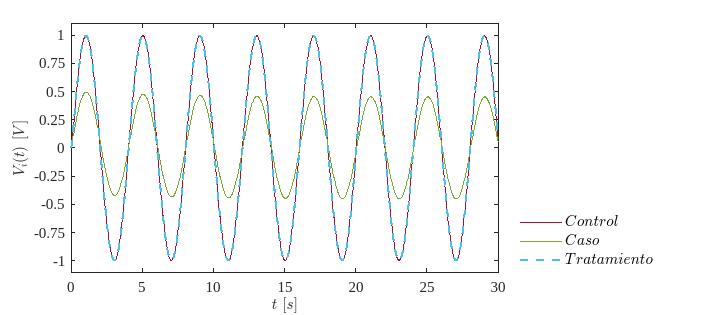

x = sim(file,parameters);
plotsignals(x.t,x.Ppx,x.Ppy,x.Ppz)

## Funciones

function plotsignals(t,Ppx,Ppy,Ppz)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on

    plot(t,Ppx,'LineWidth',1,'Color',[0.6350 0.0780 0.1840])
    plot(t,Ppy,'LineWidth',1,'Color',[0.4660 0.6740 0.1880])
    plot(t,Ppz,'--','LineWidth',1.5,'Color',[0.3010 0.7450 0.9330])

    L= legend('$Control$','$Caso$','$Tratamiento$');
    set(L,'interpreter','Latex','Fontsize',11,'Location','southeastoutside','Box','Off')

    xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11)
    ylabel('$V_i(t)$ $[V]$', 'Interpreter','Latex','FontSize',11)

    xlim([0,30]); xticks(0:5:30)
    ylim([-1.1,1.1]); yticks(-1:0.25:1)

    exportgraphics(gcf,['SistemaUrinario','.pdf'],'ContentType','vector')
    exportgraphics(gcf,['SistemaUrinario','.png'],'Resolution',600);
    print('SistemaUrinario','-dsvg','-r600');
    print('SistemaUrinario','-depsc','-r600');
end
